# Jeffery Fiber Motion using pDot

This example shows how to use the `pDot` function to find the motion of a single fiber using Jeffery's equation.  The `pDot` function provides the time derivative of $\mathbf{p}$, the unit vector that describes the fiber's orientation.

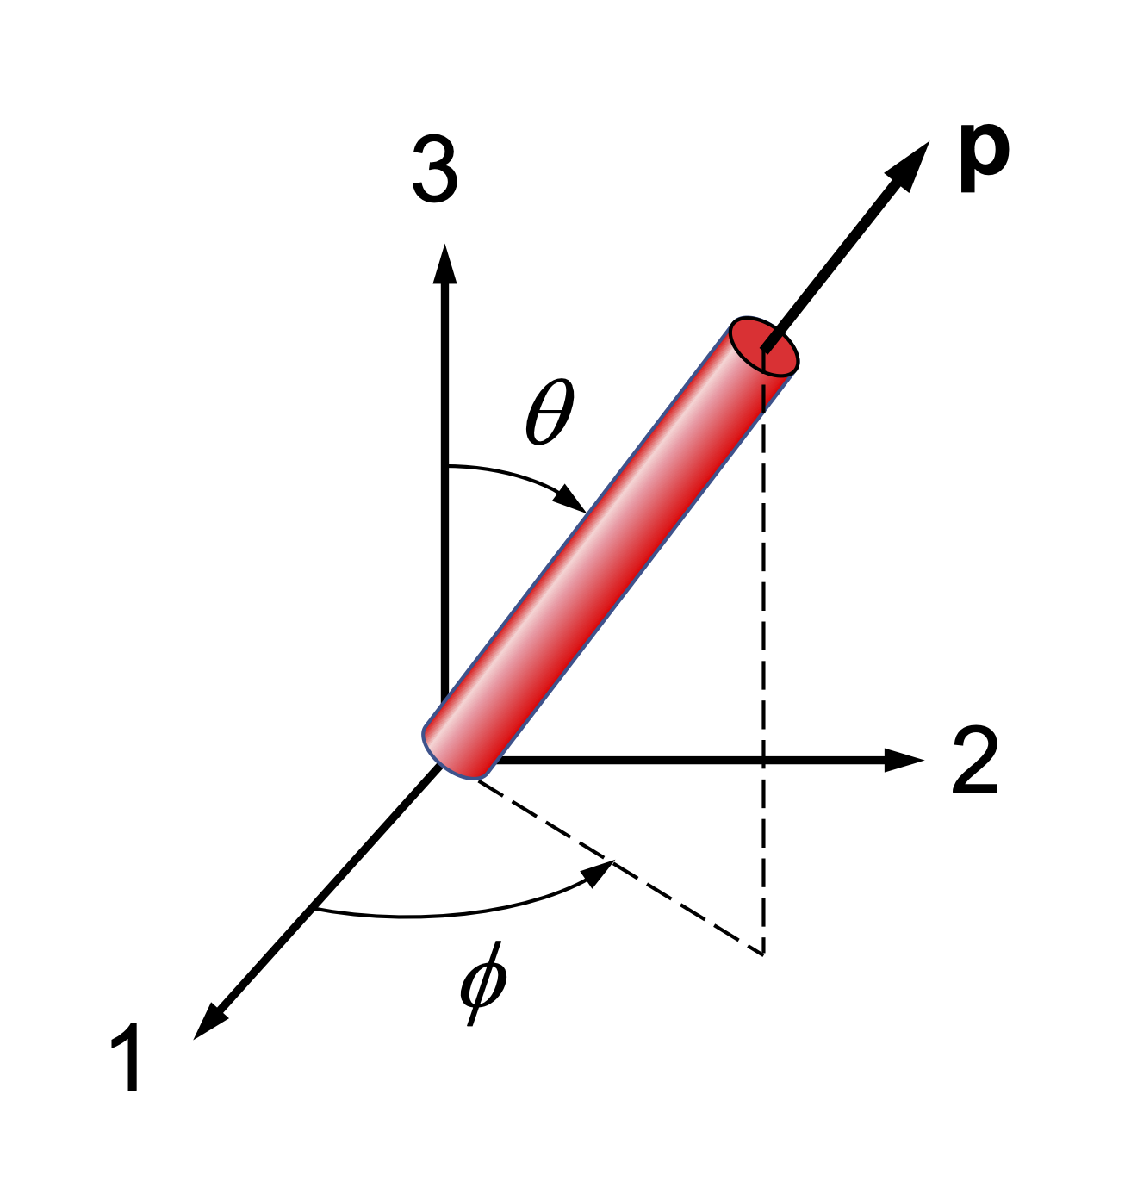

`pDot` implements Jeffery's equation, which is $\dot{\mathbf{p}} = \mathbf{W} \cdot \mathbf{p} + \xi \left( \mathbf{D} \cdot \mathbf{p} - \mathbf{D} : \mathbf{ppp} \right)$.  Here $\mathbf{D}$ is the rate-of-deformation tensor, $\mathbf{W$ is the vorticity tensor, and $\xi$ is the particle shape factor, equal to $(a^2 - b^2) / (a^2 + b^2)$ for an ellipsoidal particle with semi-axis lengths $a$, $b$ and $b$.   

To see the calling syntax for `pDot`, type

help pDot

 DPDT = pDot(P, L, XI) gives the time rate of change of the orientation 
     vector P (3x1) according to Jeffery's equation, for a velocity
     gradient tensor L (3x3) and a scalar particle shape factor XI.



To calculate the motion of a fiber over time, provide an initial value for $\mathbf{p}$, a particle shape factor, a velocity gradient tensor $\mathbf{L}$, where $L_{ij} = \partial v_i / \partial x_j$, and a set of times where the solution is desired.  Then call `ode45` to integrate the differential equation.

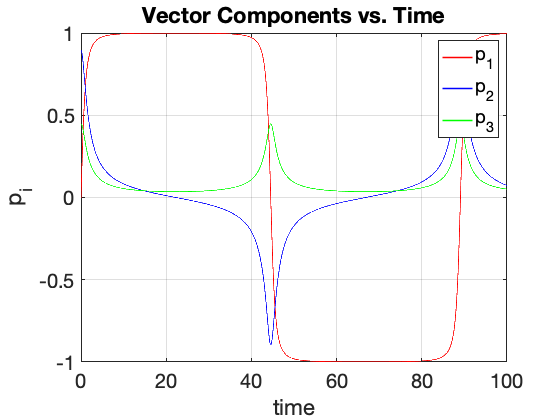

% Calculate the motion of a fiber according to Jeffery's eqn.

%% Input
pzero = [0, 1, 0.5]';       % Should be 3x1
pzero = pzero/norm(pzero);  % Ensure that pzero has unit length

L = zeros(3);               % Velocity gradient tensor
L(1,2) = 1;                 % Simple shear flow

xi = 0.99;                  % Particle shape factor

tspan = 0:0.02:100;         % Times for solution


%% Primary calculation
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-9); % Options for ode45
[t, p] = ode45(@(t,p) pDot(p, L, xi), tspan, pzero, options);

%% Simple plot of vector components
figure(1); clf
plot(t,p(:,1), 'r-', t,p(:,2),'b-', t,p(:,3),'g-', 'LineWidth', 1.5)
set(gca, 'FontSize', 20)
xlabel('time')
ylabel('p_i')
legend('p_1', 'p_2', 'p_3')
grid on
title('Vector Components vs. Time')

## Other ways to plot the data

To see the angles $\theta$ and $\phi$ vs. time, we recover them using


$$\mathbf{p} = \left\{ \begin{array}{c} \sin \theta \cos \phi \\ \sin \theta \sin \phi  \\ \cos \theta \end{array} \right\}$$


This code also keeps $\phi$ in the range of $-\phi/2 < \phi \le \phi/2$.  

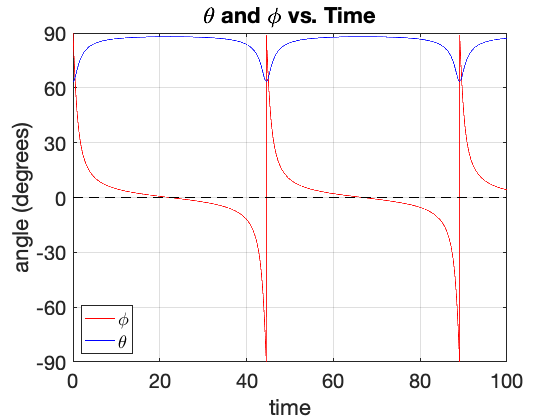

%% Recover (theta, phi) and plot them
theta = acos(p(:,3));
phi   = atan2(p(:,2), p(:,1));   % Basic eqn. for phi
phiLow = find(phi <= -pi/2);     % Indices where phi <= -pi/2.
phi(phiLow) = phi(phiLow) + pi;  % Keep -pi/2 < phi < pi/2
phiHi = find(phi > pi/2);        % Indices where phi > pi/2.
phi(phiHi) = phi(phiHi) - pi;    % Keep -pi/2 < phi < pi/2

figure(2); clf
hphi = plot(t, rad2deg(phi), 'r-', t, rad2deg(theta), 'b-');
set(gca, 'FontSize', 20)
xlabel('time')
ylabel('angle (degrees)')
axis([t(1), t(end), -90, 90])
set(gca, 'Ytick', -90:30:90)
hold on
plot([t(1), t(end)], [0, 0], 'k--') % Add black line at zero
grid on
title('\theta and \phi vs. Time')
% Legend for just the phi and theta lines
legend(hphi, '\phi', '\theta', 'Location', 'SouthWest')

Plotting the endpoints of the orientation vector is another way to show the fiber motion.  Since this example is in simple shear flow and $\xi < 1$, we can see here that the fiber repeatedly tracks along the same Jeffery orbit.  

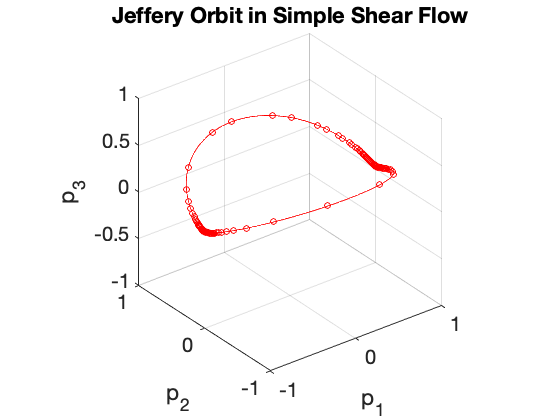

%% 3-D plot of fiber endpoints
% Shows Jeffery orbit in simple shear
figure(3); clf
h3 = plot3(p(:,1), p(:,2), p(:,3), 'r-');
hold on
% Plot selected points on the Jeffery orbit using symbols
iSymbol = 1:40:length(t);
h4 = plot3(p(iSymbol,1), p(iSymbol,2), p(iSymbol,3), 'ro');
set(gca, 'FontSize', 20)
xlabel('p_1'); ylabel('p_2'); zlabel('p_3')
axis equal
grid on
axis([-1 1 -1 1 -1 1])
title('Jeffery Orbit in Simple Shear Flow')